# 1.2.12. Анализ статистических данных

**Самостоятельная работа**

Проанализируйте данные по среднесуточной температуре в Москве за первые 3 месяца 2017 года.

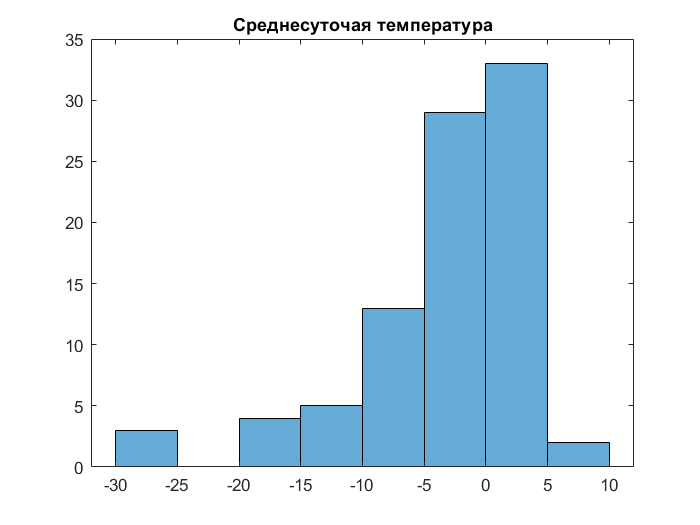

## Чтение данных

1. Считайте данные из файла `tempdata.csv` в переменную `T` типа `table` (подсказка: `readrable()`)

T = readtable('tempdata.csv');

## Создание выборки

Необходимо из загруженных температурных данных выбрать данные за первые 3 месяца - с января по март 2017 года.

2. В переменную `d1` запишите дату *1 января 2017 года* (подсказка: `datetime()`)

d1 = datetime(2017, 1, 1)

d1 = datetime
   01-Jan-2017


3. В переменную `d2` запишите дату *31 марта 2017 года*

d2 = datetime(2017, 3, 31)

d2 = datetime
   31-Mar-2017


4. В переменную `T3` запишите выборку из таблицы `T` c даты `d1` по `d2` включительно. `T3` должна иметь тип table и содержать все столбцы таблицы `T` (подсказка: используйте логическое индексирование)

T3 = T((T.DATE >= d1) & (T.DATE <= d2), :)

T3 = 90×4 table
       DATE        TMIN     TMAX     TAVG 
    ___________    _____    _____    _____

    01-Jan-2017      NaN      NaN      NaN
    02-Jan-2017      NaN      NaN      0.7
    03-Jan-2017      NaN      NaN     -6.7
    04-Jan-2017    -11.7      NaN    -10.1
    05-Jan-2017      NaN      NaN      -13
    06-Jan-2017      NaN      NaN    -25.6
    07-Jan-2017    -29.9    -23.5    -27.3
    08-Jan-2017    -28.6    -21.5    -25.2
    09-Jan-2017    -25.5      NaN    -19.9
    10-Jan-2017    -16.1     -6.7     -9.1
    11-Jan-2017      NaN      NaN     -9.7
    12-Jan-2017      -11      NaN     -8.3
    13-Jan-2017       -7       -3     -3.8
    14-Jan-2017     -5.1       -1     -2.6
    15-Jan-2017     -1.9     -0.5     -1.1
    16-Jan-2017      NaN      0.4     -1.3


## Статистический анализ

5. Постройте гистограмму среднесуточной температуры (столбец `TAVG`) из выборки `T3`. Переменная `h1` должна содержать указатель на график (подсказка: `histogram()`)

h1 = histogram(T3.TAVG);

6. Добавьте заголовок `"Среднесуточая температура"` к графику (подсказка: `title`)

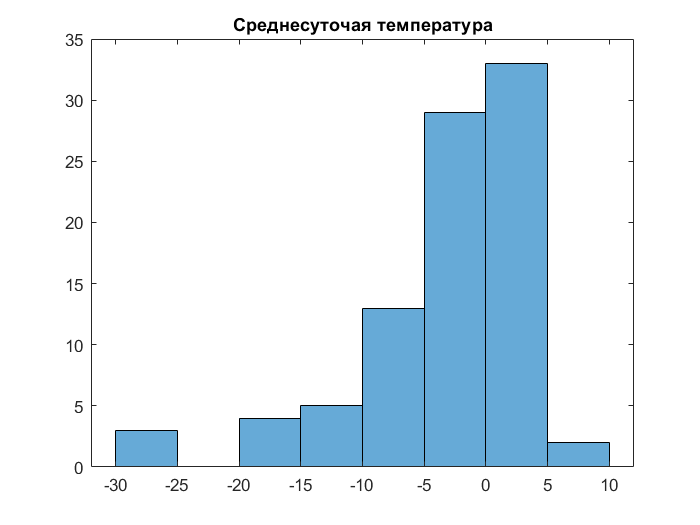

title("Среднесуточая температура")

7. В переменную `N` запишите количество дней в выборке `T3`, когда среднесуточная температура была строго больше `0`, используя логическое индексирование (подсказка: `nnz()`, `>`) 

N = nnz(T3.TAVG > 0)

N = 35

8. В переменную `cold` запишите дату, когда температура в выборке `T3` была минимальна, используя логическое индексирование (подсказка: `==`, `min()`)

cold = T.DATE(T.TAVG == min(T.TAVG))

cold = datetime
   07-Jan-2017
